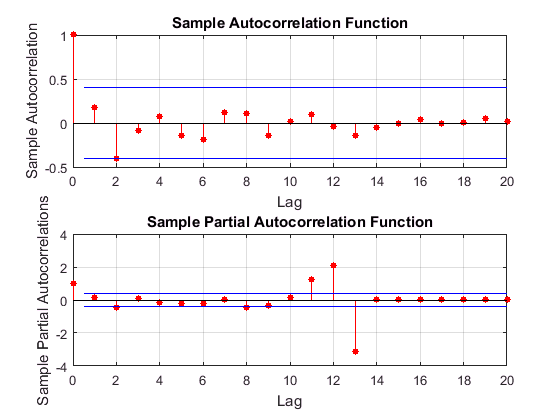

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ARIMA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
MaN = 11;
SiN = 3;
TN = 100 + MaN;
SN = 36;
FN = 24;
% [sigP,mainP]= movavg(ML_M5.Close(1301:1300+TN),SiN,MaN,'e');
% sigP = sigP(MaN:end);
% mainP = mainP(MaN:end);
prc = (ML_M5.High(520:620) + ML_M5.Low(520:620))/2;
lr = price2ret(prc);
df = diff(prc);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Analyzing & Deciding Models
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
subplot(2,1,1);
autocorr(df(1:SN));
subplot(2,1,2);
parcorr(df(1:SN));

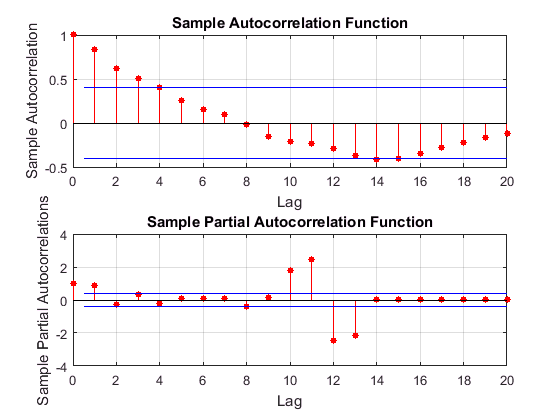

figure;
subplot(2,1,1);
autocorr(prc(1:SN));
subplot(2,1,2);
parcorr(prc(1:SN));

mdlPrc = arima('Constant',0,'ARLags',1,'D',1);
estPrc = estimate(mdlPrc,prc(1:SN));

 
    ARIMA(1,1,0) Model:
    --------------------
    Conditional Probability Distribution: Gaussian

                                  Standard          t     
     Parameter       Value          Error       Statistic 
    -----------   -----------   ------------   -----------
     Constant              0         Fixed          Fixed
        AR{1}       0.195032       0.15635         1.2474
     Variance        1.94572      0.399653        4.86852


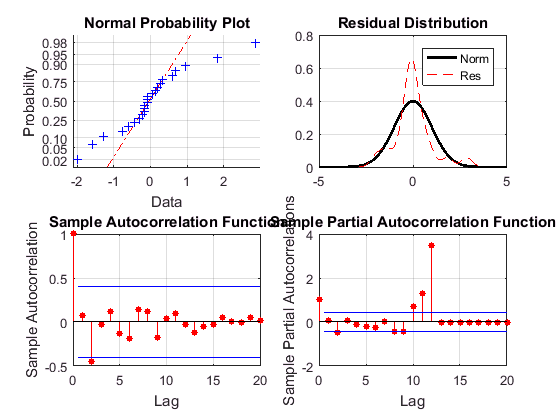

se = infer(estPrc,prc(1:SN));
st_se = zscore(se);
[f,xi] = ksdensity(st_se);
x = -5:.05:5;
figure;
subplot(2,2,1);
normplot(st_se);
subplot(2,2,2);
plot(x,normpdf(x),'k','LineWidth',2);
hold on;
plot(xi,f,'r--');
hold off;
grid;
title('Residual Distribution');
legend('Norm','Res');
subplot(2,2,3);
autocorr(se);
subplot(2,2,4);
parcorr(se);

rng('default');
Yset = simulate(estPrc,FN,'NumPaths',1000,'Y0',prc(1:SN));
res = (Yset(1:12,:) - prc(SN+1:SN+12)) .^ 2;
[mse,mseIdx] = min(sum(res))

mse = 57.4001

mseIdx = 832

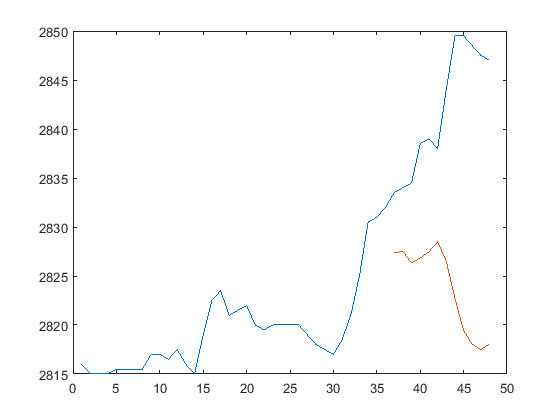

figure;
plot(prc(1:SN+FN));
hold on;
plot(SN+13:SN+FN,Yset(13:end,mseIdx));
hold off;

%rng(10,'v5uniform');
% Yset = simulate(estPrc,FN,'NumPaths',2,'Y0',prc(1:SN),'V0',estPrc.Variance,'E0',se);
% figure;
% plot(prc(1:SN+FN));
% hold on;
% plot(SN+1:SN+FN,mean(Yset,2));
% hold off;
% figure;
% subplot(2,1,1);
% autocorr(df(1:SN));
% subplot(2,1,2);
% parcorr(df(1:SN));
% figure;
% subplot(2,1,1);
% autocorr(sigP(1:SN));
% subplot(2,1,2);
% parcorr(sigP(1:SN));
% mdlSig = arima('Constant',0,'ARLags',1:2,'SARLags',12,'D',1);
% estSig = estimate(mdlSig,sigP(1:SN));
% se = infer(estSig,sigP(1:SN));
% st_se = zscore(se);
% [f,xi] = ksdensity(st_se);
% x = -5:.05:5;
% figure;
% subplot(2,2,1);
% normplot(st_se);
% subplot(2,2,2);
% plot(x,normpdf(x),'k','LineWidth',2);
% hold on;
% plot(xi,f,'r--');
% hold off;
% grid;
% title('Residual Distribution');
% legend('Norm','Res');
% subplot(2,2,3);
% autocorr(se);
% subplot(2,2,4);
% parcorr(se);
% figure;
% subplot(2,1,1);
% autocorr(mainP(1:SN));
% subplot(2,1,2);
% parcorr(mainP(1:SN));
% mdlMain = arima('Constant',0,'ARLags',1:2,'D',1);
% estMain = estimate(mdlMain,mainP(1:SN));
% me = infer(estMain,mainP(1:SN));
% st_me = zscore(me);
% [f,xi] = ksdensity(st_me);
% x = -5:.05:5;
% figure;
% subplot(2,2,1);
% normplot(st_me);
% subplot(2,2,2);
% plot(x,normpdf(x),'k','LineWidth',2);
% hold on;
% plot(xi,f,'r--');
% hold off;
% grid;
% title('Residual Distribution');
% legend('Norm','Res');
% subplot(2,2,3);
% autocorr(me);
% subplot(2,2,4);
% parcorr(me);
% rng('default');
% ySig = simulate(estSig,FN,'NumPaths',5,'Y0',sigP(1:SN));
% rng('default');
% yMain = simulate(estMain,FN,'NumPaths',5,'Y0',mainP(1:SN));
% figure;
% plot(prc,'k');
% fh = gca;
% fh.XLim = [1,TN];
% fh.XTick = 1:floor(TN/8):TN;
% fh.XTickLabel = datestr(dt(1:floor(TN/8):TN));
% hold on;
% plot(TN-FN+1:TN,mean(ysim,2),'r');
% hold off;
% grid;
% title('Forecast Price');
% xlabel('Time');
% ylabel('Price');
% legend('Real','Forecast');
% res = mp(TN-FN+1:TN)-mean(ysim,2);
% figure;
% scatter(1:FN,res,'filled');
% grid;
% xlabel('Series No.');
% ylabel('Residuals');
% title('Residuals Scatter');
% ste = zscore(res);
% [f,xi] = ksdensity(ste);
% x = -5:.05:5;
% figure;
% subplot(2,2,1);
% normplot(ste);
% subplot(2,2,2);
% plot(x,normpdf(x),'k','LineWidth',1.5);
% hold on;
% plot(xi,f,'r--');
% hold off;
% grid;
% title('Residual Distribution');
% legend('Norm','Res');
% subplot(2,2,3);
% autocorr(ste);
% subplot(2,2,4);
% parcorr(ste);
% archtest(res)
% adftest(res)
% lbqtest(res)
% res2 = res.^2;
% figure;
% subplot(2,1,1);
% autocorr(res2);
% subplot(2,1,2);
% parcorr(res2);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % GARCH
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% lr = price2ret(mp)*100;
% figure;
% scatter(1:TN-1,lr);
% grid;
% axh = gca;
% axh.XLim = [1,TN-1];
% axh.XTick = 1:floor(TN/8):TN-1;
% axh.XTickLabel = datestr(dt(1:floor(TN/8):TN-1),25);
% xlabel('Date');
% ylabel('Log Return Ratio');
% title('Soybean Meal');
% legend('Log Return Ratio');
% figure;
% subplot(2,1,1);
% autocorr(lr);
% subplot(2,1,2);
% parcorr(lr);
% e = lr - mean(lr);
% archtest(e,'lags',1:20)
% see = e.^2;
% figure;
% subplot(2,1,1);
% autocorr(see);
% subplot(2,1,2);
% parcorr(see);